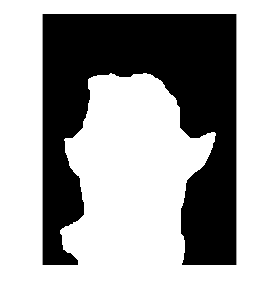

clear
img = imread("../db/DB1/db1_14.jpg");
hybrid_mask = hybrid(img);
hold off
% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

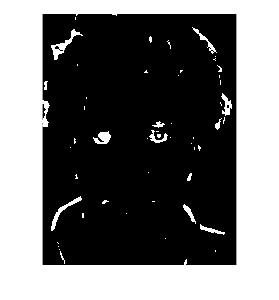


%Find eyes and a mouth
eyes = eyemap(img_gw);



imshow(hybrid_mask)

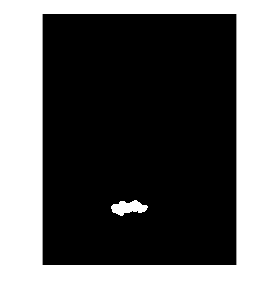


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask);


mouth_center = [x, y]; % replace with actual coordinates

% [indexX,indexY] = eye_index(hybrid_mask)



for radii = 10:5:25
    eye_mask = eyemask(eyes,face_mask);
    [indexX,indexY] = eye_index(eye_mask)
    [eye1 , eye2] = findEyePair(indexX,indexY,mouth_center);
    if (eye1(1) < mouth_center(1) && eye1(2) > mouth_center(1))  || (eye1(1) > mouth_center(1) && eye1(2) < mouth_center(1))
        break
    end
end

indexX =    66.6564  128.4139  219.0882  253.9404


indexY =   272.6256  260.4868  130.4608  258.0317


Index in position 1 exceeds array bounds.

Error in findEyePair (line 93)
    eye1 = selected_eyes(1, :);


% [eye1, eye2] = iterativeEyeFinder(eyes,face_mask,mouth_center);


hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')